## Project 2 - Activity Monitor

clear
clc

#### 1. Generate ActivityMonitor object. 

Initialize the ActivityMonitor object and import the dataset to be analysed. name the run a number so they can be differentiated.

obj = ActivityMonitor;

Object Initiated


obj.name = 1;

#### 2. Clean and prepare dataset for analysis. 

Cut off the junk data at the start and end, as well as add labels if an accuracy score is desired.

At the beginning and end of any acceleration measurement will be some junk data, from when youre using your phone, waving it around to put it in/out of your pocket, and preparing/stopping the measurement. for best results this data should be removed. The best approach is to remove small amounts until the data is the required length. 

Optionally, labels may be added to the dataset, which will allow an accuracy score to be calculated later.

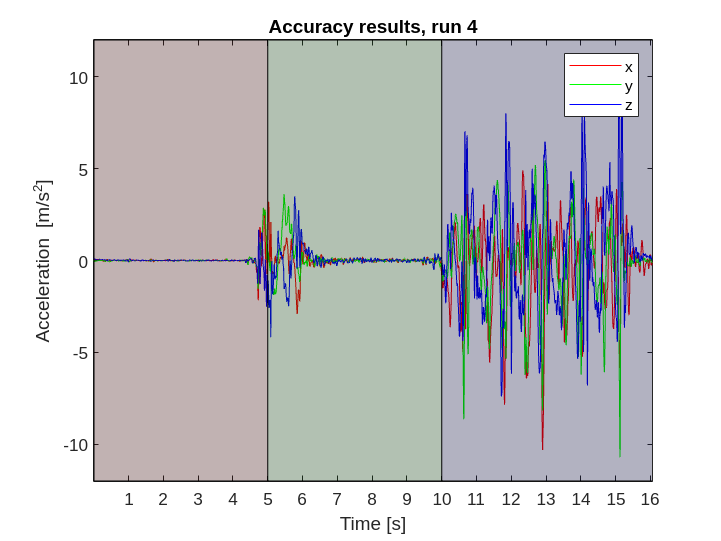

Data cleaning complete


obj = obj.data_cleaner;

#### 3. Analyse Data

use the abs() and movmean() functions to preprocess the data, then use the threshold values to determine what state the user is in at every given timestep.

If labels were given in the last step, calculate an accuracy score.

Accuracy score : 84.8%


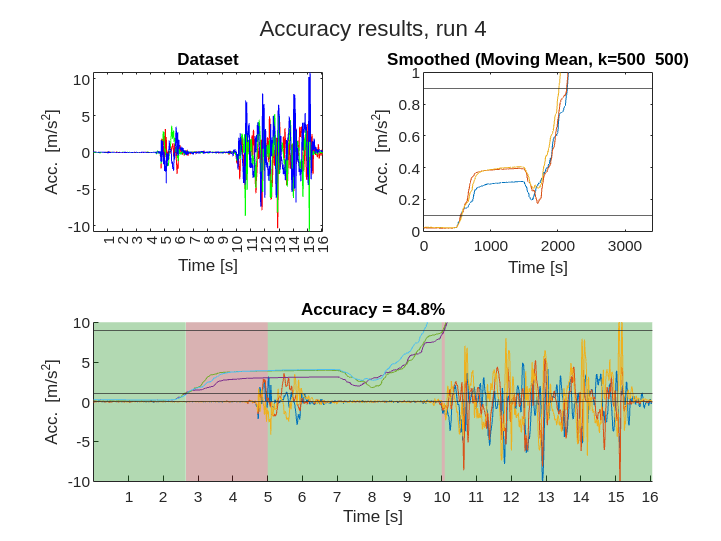

obj.smooth_k = [500, 500];
obj.thresholds = [0.1, 0.9];

obj = obj.analyse_data;

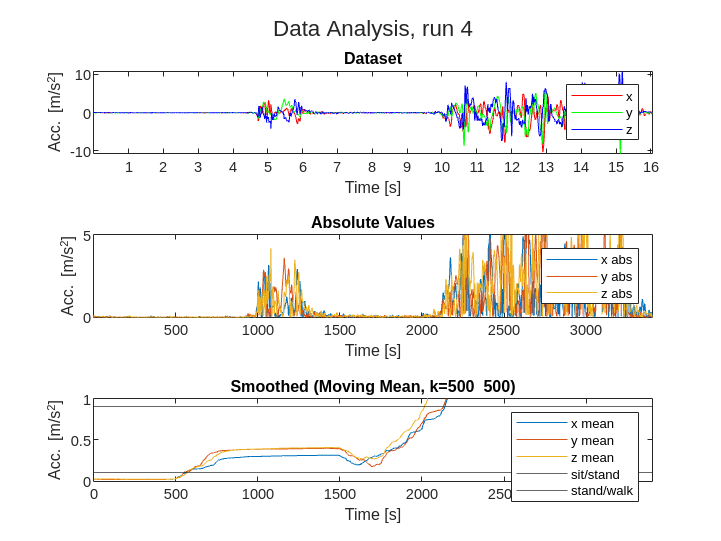

%plot data analysis
obj.plot_abs_movmean;

#### 4. Get state between timesteps

input a beginning and an end time that enclose a single state, and predict what that state is.

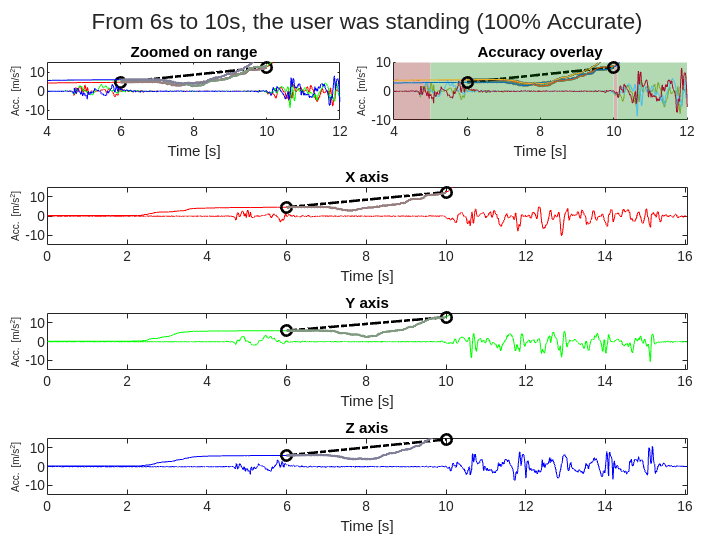

obj.predict_in_range;

#### 5. Determine Final Results

Collate together results from multiple datasets and plot their accuracy results. use this to determine an optimal smooth_k and threshold to input in the analyse data step.

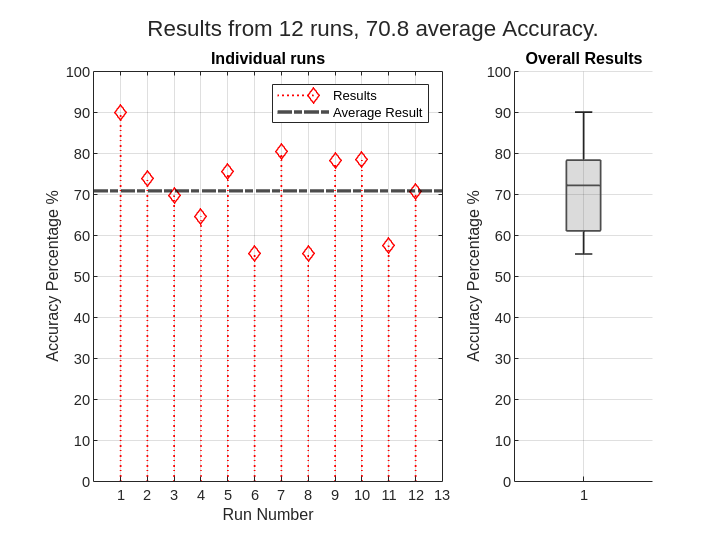

results = [90, 73.7, 69.7, 64.6, 75.5, 55.5, 80.5, 55.4, 78.1, 78.5, 57.5, 70.6];

obj.plot_results(results);